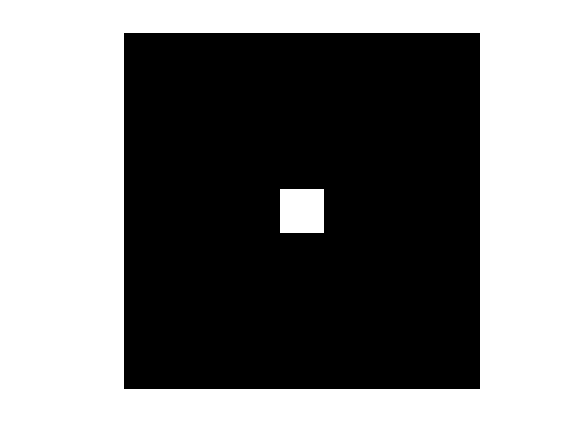

 F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
 G = F';
 showgrey(F .* G); % multiplication

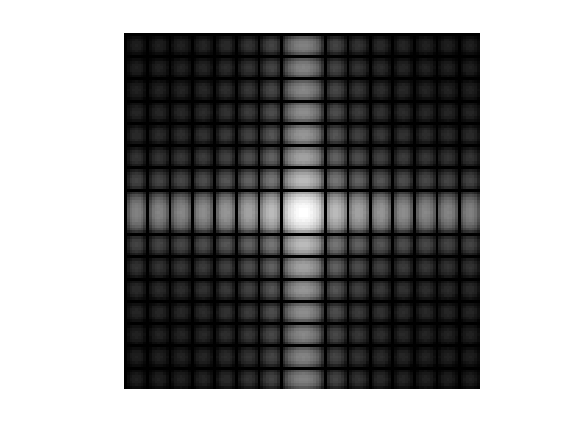

 showfs(fft2(F .* G)); % becomes convolution

 
 
 Fhat = (1/length(F))* fft2(F); % fourier transform
 Ghat = (1/length(G)) * fft2(G); % fourer transform
 
 % same but go backwards
 result = conv2(Ghat, Fhat); % convolution
 result = result(1:128, 1:128); % remove the unnecessary part of convolution, right dimension. 
 showfs(result); 

 showfs(fftshift(ifft2(result)))  